# Voltage clamp recordings for preferred and null directions

Measuring excitation and inhibition for high and low contrast moving bars in the preferred and null directions. One question to ask is does the E/I ratio change across contrasts.

ups = grabFromFilter('UP Cells');
downs = grabFromFilter('DOWN Cells');

%choose which protocols to look at
priorityOrder_1 = {'Moving_Bar'}; %first field name should be one of these. Priority is in given order
priorityOrder_2 = {'_PDND_'}; %child field name should be one of these. Priority is in given order
mustHave_1 = [];
mustHave_2 = {'Intracellular', 'Excitation', '_Intensity0d1'};
mustHave_2b = {'Intracellular', 'Excitation', '_Intensity0d5'};
mustHave_2c = {'Intracellular', 'Inhibition', '_Intensity0d1'};
mustHave_2d = {'Intracellular', 'Inhibition', '_Intensity0d5'};
cantHave_1 = [];
cantHave_2 = {'Extracellular', 'Potassium'}; %avoid anything with these tags
rigMandates = []; %no rig mandates


EI_LowContrast_PD_up = [];
EI_LowContrast_ND_up = [];
EI_HighContrast_PD_up = [];
EI_HighContrast_ND_up = [];

E_HighContrast_PD_up = [];
E_LowContrast_PD_up = [];
E_HighContrast_ND_up = [];
E_LowContrast_ND_up = [];
I_HighContrast_PD_up = [];
I_LowContrast_PD_up = [];
I_HighContrast_ND_up = [];
I_LowContrast_ND_up= [];
for i = 1:size(ups, 1)
    struct_i = ups{i, 2};
    [loc_EL, pass_EL] = getLoc(struct_i, priorityOrder_1, mustHave_1, cantHave_1, priorityOrder_2, mustHave_2, cantHave_2, rigMandates);
    [loc_EH, pass_EH] = getLoc(struct_i, priorityOrder_1, mustHave_1, cantHave_1, priorityOrder_2, mustHave_2b, cantHave_2, rigMandates);
    [loc_IL, pass_IL] = getLoc(struct_i, priorityOrder_1, mustHave_1, cantHave_1, priorityOrder_2, mustHave_2c, cantHave_2, rigMandates);
    [loc_IH, pass_IH] = getLoc(struct_i, priorityOrder_1, mustHave_1, cantHave_1, priorityOrder_2, mustHave_2d, cantHave_2, rigMandates);
    if pass_EL || pass_EH || pass_IL || pass_IH
        continue
    end
    orientationsLookup = @(s) sort(s.Analysis_Results.Orientation);
    orientationsEL = orientationsLookup(loc_EL); orientationsEH = orientationsLookup(loc_EH);
    orientationsIL = orientationsLookup(loc_IL); orientationsIH = orientationsLookup(loc_IH);
    
    %make sure all groups used the same stimulus orientations
    if ~(orientationsEL == orientationsEH & orientationsEH == orientationsIL...
            & orientationsIL == orientationsIH)
    continue
    end
    
    [~, PDstimDirectionIndex] = min(abs(90 - orientationsEL));
    PDStimDirection = orientationsEL(PDstimDirectionIndex);
    
    [~, NDstimDirectionIndex] = min(abs(270 - orientationsEL));
    NDStimDirection = orientationsEL(NDstimDirectionIndex);
    
    PDEpochs_EL = (loc_EL.Analysis_Results.orientationByEpoch == PDStimDirection);
    NDEpochs_EL = (loc_EL.Analysis_Results.orientationByEpoch == NDStimDirection);
    PDMax_EL = -mean(loc_EL.Analysis_Results.maxNegativePeakByEpoch(PDEpochs_EL));
    NDMax_EL = -mean(loc_EL.Analysis_Results.maxNegativePeakByEpoch(NDEpochs_EL));
    
    PDEpochs_EH = (loc_EH.Analysis_Results.orientationByEpoch == PDStimDirection);
    NDEpochs_EH = (loc_EH.Analysis_Results.orientationByEpoch == NDStimDirection);
    PDMax_EH = -mean(loc_EH.Analysis_Results.maxNegativePeakByEpoch(PDEpochs_EH));
    NDMax_EH = -mean(loc_EH.Analysis_Results.maxNegativePeakByEpoch(NDEpochs_EH));
    
    PDEpochs_IL = (loc_IL.Analysis_Results.orientationByEpoch == PDStimDirection);
    NDEpochs_IL = (loc_IL.Analysis_Results.orientationByEpoch == NDStimDirection);
    PDMax_IL = mean(loc_IL.Analysis_Results.maxPositivePeakByEpoch(PDEpochs_IL));
    NDMax_IL = mean(loc_IL.Analysis_Results.maxPositivePeakByEpoch(NDEpochs_IL));
    
    PDEpochs_IH = (loc_IH.Analysis_Results.orientationByEpoch == PDStimDirection);
    NDEpochs_IH = (loc_IH.Analysis_Results.orientationByEpoch == NDStimDirection);
    PDMax_IH = mean(loc_IH.Analysis_Results.maxPositivePeakByEpoch(PDEpochs_IH));
    NDMax_IH = mean(loc_IH.Analysis_Results.maxPositivePeakByEpoch(NDEpochs_IH));
    
    EI_LowContrast_PD_up(end+1)  = PDMax_EL/PDMax_IL;
    EI_LowContrast_ND_up(end+1) = NDMax_EL/NDMax_IL;
    EI_HighContrast_PD_up(end+1) = PDMax_EH/PDMax_IH;
    EI_HighContrast_ND_up(end+1) = NDMax_EH/NDMax_IH;
    
    E_HighContrast_PD_up(end+1) = PDMax_EH;
    E_LowContrast_PD_up(end+1) = PDMax_EL;
    E_HighContrast_ND_up(end+1) = NDMax_EH;
    E_LowContrast_ND_up(end+1) = NDMax_EL;
    I_HighContrast_PD_up(end+1) = PDMax_IH;
    I_LowContrast_PD_up(end+1) = PDMax_IL;
    I_HighContrast_ND_up(end+1) = NDMax_IH;
    I_LowContrast_ND_up(end+1)= NDMax_IL;
end

EI_LowContrast_PD_down = [];
EI_LowContrast_ND_down = [];
EI_HighContrast_PD_down = [];
EI_HighContrast_ND_down = [];

E_HighContrast_PD_down = [];
E_LowContrast_PD_down = [];
E_HighContrast_ND_down = [];
E_LowContrast_ND_down = [];
I_HighContrast_PD_down = [];
I_LowContrast_PD_down = [];
I_HighContrast_ND_down = [];
I_LowContrast_ND_down= [];
for i = 1:size(downs, 1)
    struct_i = downs{i, 2};
    [loc_EL, pass_EL] = getLoc(struct_i, priorityOrder_1, mustHave_1, cantHave_1, priorityOrder_2, mustHave_2, cantHave_2, rigMandates);
    [loc_EH, pass_EH] = getLoc(struct_i, priorityOrder_1, mustHave_1, cantHave_1, priorityOrder_2, mustHave_2b, cantHave_2, rigMandates);
    [loc_IL, pass_IL] = getLoc(struct_i, priorityOrder_1, mustHave_1, cantHave_1, priorityOrder_2, mustHave_2c, cantHave_2, rigMandates);
    [loc_IH, pass_IH] = getLoc(struct_i, priorityOrder_1, mustHave_1, cantHave_1, priorityOrder_2, mustHave_2d, cantHave_2, rigMandates);
    if pass_EL || pass_EH || pass_IL || pass_IH
        continue
    end
    orientationsLookup = @(s) sort(s.Analysis_Results.Orientation);
    orientationsEL = orientationsLookup(loc_EL); orientationsEH = orientationsLookup(loc_EH);
    orientationsIL = orientationsLookup(loc_IL); orientationsIH = orientationsLookup(loc_IH);
    
    %make sure all groups used the same stimulus orientations
    if ~(orientationsEL == orientationsEH & orientationsEH == orientationsIL...
            & orientationsIL == orientationsIH)
    continue
    end
    
    [~, PDstimDirectionIndex] = min(abs(270 - orientationsEL));
    PDStimDirection = orientationsEL(PDstimDirectionIndex);
    
    [~, NDstimDirectionIndex] = min(abs(90 - orientationsEL));
    NDStimDirection = orientationsEL(NDstimDirectionIndex);
    
    PDEpochs_EL = (loc_EL.Analysis_Results.orientationByEpoch == PDStimDirection);
    NDEpochs_EL = (loc_EL.Analysis_Results.orientationByEpoch == NDStimDirection);
    PDMax_EL = -mean(loc_EL.Analysis_Results.maxNegativePeakByEpoch(PDEpochs_EL));
    NDMax_EL = -mean(loc_EL.Analysis_Results.maxNegativePeakByEpoch(NDEpochs_EL));
    
    PDEpochs_EH = (loc_EH.Analysis_Results.orientationByEpoch == PDStimDirection);
    NDEpochs_EH = (loc_EH.Analysis_Results.orientationByEpoch == NDStimDirection);
    PDMax_EH = -mean(loc_EH.Analysis_Results.maxNegativePeakByEpoch(PDEpochs_EH));
    NDMax_EH = -mean(loc_EH.Analysis_Results.maxNegativePeakByEpoch(NDEpochs_EH));
    
    PDEpochs_IL = (loc_IL.Analysis_Results.orientationByEpoch == PDStimDirection);
    NDEpochs_IL = (loc_IL.Analysis_Results.orientationByEpoch == NDStimDirection);
    PDMax_IL = mean(loc_IL.Analysis_Results.maxPositivePeakByEpoch(PDEpochs_IL));
    NDMax_IL = mean(loc_IL.Analysis_Results.maxPositivePeakByEpoch(NDEpochs_IL));
    
    PDEpochs_IH = (loc_IH.Analysis_Results.orientationByEpoch == PDStimDirection);
    NDEpochs_IH = (loc_IH.Analysis_Results.orientationByEpoch == NDStimDirection);
    PDMax_IH = mean(loc_IH.Analysis_Results.maxPositivePeakByEpoch(PDEpochs_IH));
    NDMax_IH = mean(loc_IH.Analysis_Results.maxPositivePeakByEpoch(NDEpochs_IH));
    
    EI_LowContrast_PD_down(end+1)  = PDMax_EL/PDMax_IL;
    EI_LowContrast_ND_down(end+1) = NDMax_EL/NDMax_IL;
    EI_HighContrast_PD_down(end+1) = PDMax_EH/PDMax_IH;
    EI_HighContrast_ND_down(end+1) = NDMax_EH/NDMax_IH;
    
    E_HighContrast_PD_down(end+1) = PDMax_EH;
    E_LowContrast_PD_down(end+1) = PDMax_EL;
    E_HighContrast_ND_down(end+1) = NDMax_EH;
    E_LowContrast_ND_down(end+1) = NDMax_EL;
    I_HighContrast_PD_down(end+1) = PDMax_IH;
    I_LowContrast_PD_down(end+1) = PDMax_IL;
    I_HighContrast_ND_down(end+1) = NDMax_IH;
    I_LowContrast_ND_down(end+1)= NDMax_IL;
end


## E/I across contrasts

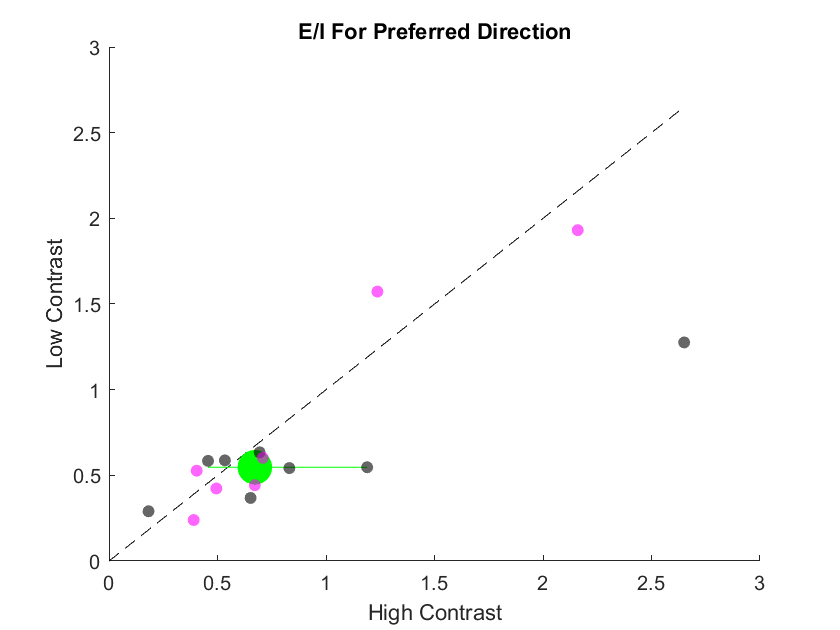

medianX = median([EI_HighContrast_PD_up, EI_HighContrast_PD_down]);
medianY = median([EI_LowContrast_PD_up, EI_LowContrast_PD_down]);
[~, ~, xER1, xER2] = medianCI95Bootstrap([EI_HighContrast_PD_up, EI_HighContrast_PD_down], 10000);
[~, ~, yER1, yER2] = medianCI95Bootstrap([EI_LowContrast_PD_up, EI_LowContrast_PD_down], 10000);


%Start with preferred direction
figure
title('E/I For Preferred Direction')
hold on
plot([0 2.65], [0, 2.65 ], '--k')
scatter(medianX, medianY, 300, 'filled', 'g')
plot([-xER1, xER2] + medianX, [medianY, medianY], 'g')
plot([medianX, medianX], [-yER1, yER2] + medianY, 'g')
scatter(EI_HighContrast_PD_up, EI_LowContrast_PD_up, 'k', 'filled', 'MarkerFaceAlpha', 0.6)
scatter(EI_HighContrast_PD_down, EI_LowContrast_PD_down, 'm', 'filled', 'MarkerFaceAlpha', 0.6)
xlabel('High Contrast')
ylabel('Low Contrast')


p = signrank([EI_HighContrast_PD_up, EI_HighContrast_PD_down],...
    [EI_LowContrast_PD_up, EI_LowContrast_PD_down])

p = 0.1205

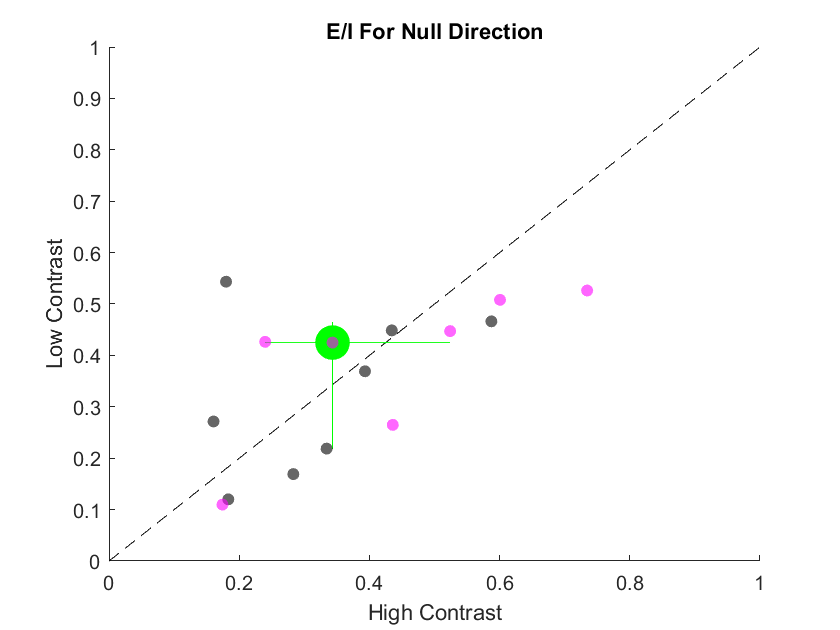

medianX = median([EI_HighContrast_ND_up, EI_HighContrast_ND_down]);
medianY = median([EI_LowContrast_ND_up, EI_LowContrast_ND_down]);
[~, ~, xER1, xER2] = medianCI95Bootstrap([EI_HighContrast_ND_up, EI_HighContrast_ND_down], 10000);
[~, ~, yER1, yER2] = medianCI95Bootstrap([EI_LowContrast_ND_up, EI_LowContrast_ND_down], 10000);


%Start with preferred direction
figure
title('E/I For Null Direction')
hold on
plot([0 1], [0, 1], '--k')
scatter(medianX, medianY, 300, 'filled', 'g')
plot([-xER1, xER2] + medianX, [medianY, medianY], 'g')
plot([medianX, medianX], [-yER1, yER2] + medianY, 'g')
scatter(EI_HighContrast_ND_up, EI_LowContrast_ND_up, 'k', 'filled', 'MarkerFaceAlpha', 0.6)
scatter(EI_HighContrast_ND_down, EI_LowContrast_ND_down, 'm', 'filled', 'MarkerFaceAlpha', 0.6)
xlabel('High Contrast')
ylabel('Low Contrast')

p = signrank([EI_HighContrast_ND_up, EI_HighContrast_ND_down],...
    [EI_LowContrast_ND_up, EI_LowContrast_ND_down])

p = 0.3591

% Also consider chi squared test for proportion of observations that are
% higher for low contrast vs same thing for DSI or Normed Area spikes.
overUnity_PD = [EI_HighContrast_PD_up, EI_HighContrast_PD_down] > [EI_LowContrast_PD_up, EI_LowContrast_PD_down];
proportion_PD = sum(overUnity_PD)/numel(overUnity_PD)

proportion_PD = 0.6667


overUnity_ND = [EI_HighContrast_ND_up, EI_HighContrast_ND_down] > [EI_LowContrast_ND_up, EI_LowContrast_ND_down];
proportion_ND = sum(overUnity_ND)/numel(overUnity_ND)

proportion_ND = 0.6667

## Manginute of E and I for PD and ND

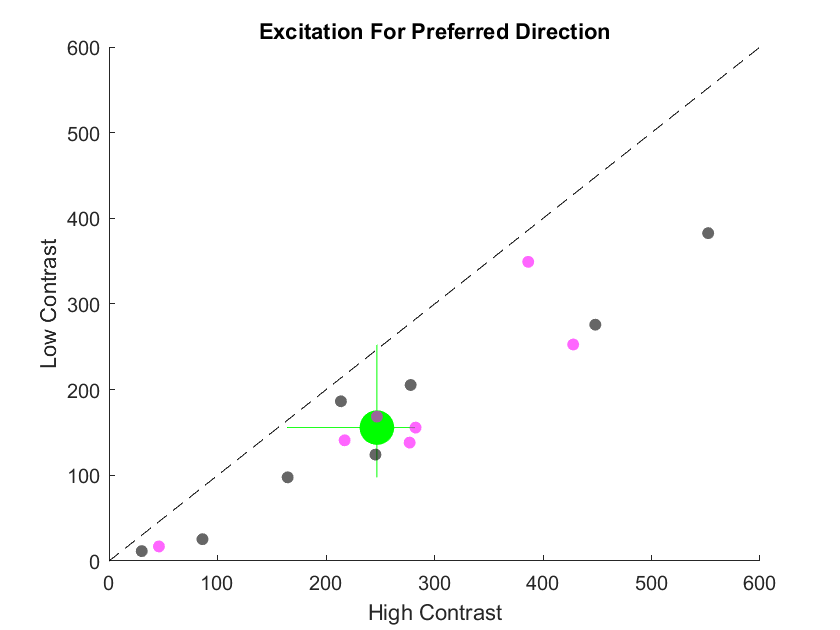

medianX = median([E_HighContrast_PD_up, E_HighContrast_PD_down]);
medianY = median([E_LowContrast_PD_up, E_LowContrast_PD_down]);
[~, ~, xER1, xER2] = medianCI95Bootstrap([E_HighContrast_PD_up, E_HighContrast_PD_down], 10000);
[~, ~, yER1, yER2] = medianCI95Bootstrap([E_LowContrast_PD_up, E_LowContrast_PD_down], 10000);


%Start with preferred direction
figure
title('Excitation For Preferred Direction')
hold on
plot([0 600], [0, 600], '--k')
scatter(medianX, medianY, 300, 'filled', 'g')
plot([-xER1, xER2] + medianX, [medianY, medianY], 'g')
plot([medianX, medianX], [-yER1, yER2] + medianY, 'g')
scatter(E_HighContrast_PD_up, E_LowContrast_PD_up, 'k', 'filled', 'MarkerFaceAlpha', 0.6)
scatter(E_HighContrast_PD_down, E_LowContrast_PD_down, 'm', 'filled', 'MarkerFaceAlpha', 0.6)
xlabel('High Contrast')
ylabel('Low Contrast')

p = signrank([E_HighContrast_PD_up, E_HighContrast_PD_down],...
    [E_LowContrast_PD_up, E_LowContrast_PD_down])

p = 6.1035e-05

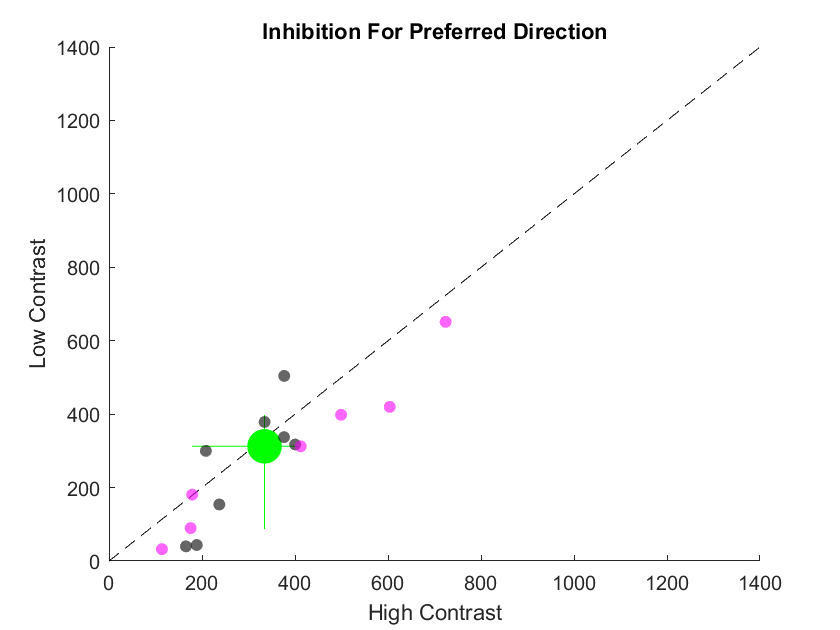


medianX = median([I_HighContrast_PD_up, I_HighContrast_PD_down]);
medianY = median([I_LowContrast_PD_up, I_LowContrast_PD_down]);
[~, ~, xER1, xER2] = medianCI95Bootstrap([I_HighContrast_PD_up, I_HighContrast_PD_down], 10000);
[~, ~, yER1, yER2] = medianCI95Bootstrap([I_LowContrast_PD_up, I_LowContrast_PD_down], 10000);


%Start with preferred direction
figure
title('Inhibition For Preferred Direction')
hold on
plot([0 1400], [0, 1400], '--k')
scatter(medianX, medianY, 300, 'filled', 'g')
plot([-xER1, xER2] + medianX, [medianY, medianY], 'g')
plot([medianX, medianX], [-yER1, yER2] + medianY, 'g')
scatter(I_HighContrast_PD_up, I_LowContrast_PD_up, 'k', 'filled', 'MarkerFaceAlpha', 0.6)
scatter(I_HighContrast_PD_down, I_LowContrast_PD_down, 'm', 'filled', 'MarkerFaceAlpha', 0.6)
xlabel('High Contrast')
ylabel('Low Contrast')

p = signrank([I_HighContrast_PD_up, I_HighContrast_PD_down],...
    [I_LowContrast_PD_up, I_LowContrast_PD_down])

p = 0.0554

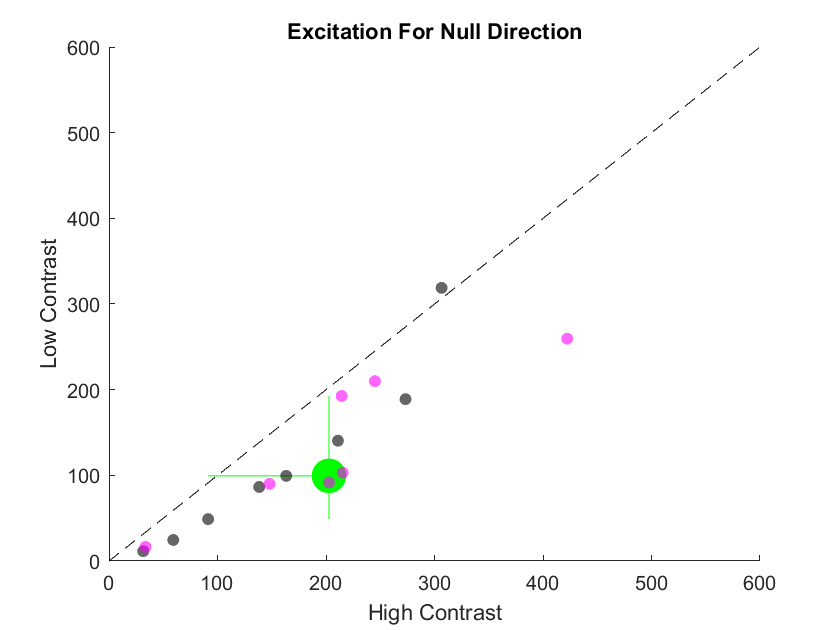


medianX = median([E_HighContrast_ND_up, E_HighContrast_ND_down]);
medianY = median([E_LowContrast_ND_up, E_LowContrast_ND_down]);
[~, ~, xER1, xER2] = medianCI95Bootstrap([E_HighContrast_ND_up, E_HighContrast_ND_down], 10000);
[~, ~, yER1, yER2] = medianCI95Bootstrap([E_LowContrast_ND_up, E_LowContrast_ND_down], 10000);


%Start with preferred direction
figure
title('Excitation For Null Direction')
hold on
plot([0 600], [0, 600], '--k')
scatter(medianX, medianY, 300, 'filled', 'g')
plot([-xER1, xER2] + medianX, [medianY, medianY], 'g')
plot([medianX, medianX], [-yER1, yER2] + medianY, 'g')
scatter(E_HighContrast_ND_up, E_LowContrast_ND_up, 'k', 'filled', 'MarkerFaceAlpha', 0.6)
scatter(E_HighContrast_ND_down, E_LowContrast_ND_down, 'm', 'filled', 'MarkerFaceAlpha', 0.6)
xlabel('High Contrast')
ylabel('Low Contrast')

p = signrank([E_HighContrast_ND_up, E_HighContrast_ND_down],...
    [E_LowContrast_ND_up, E_LowContrast_ND_down])

p = 1.2207e-04

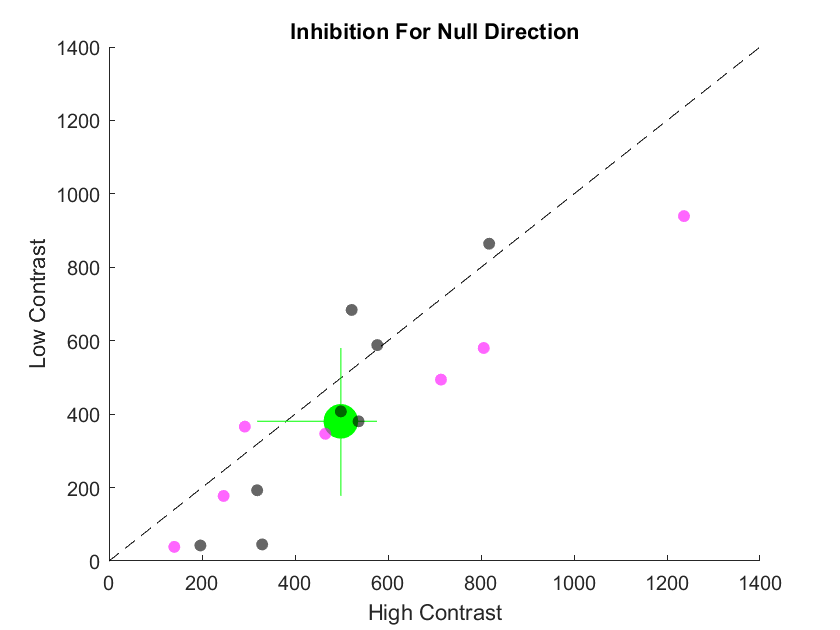


medianX = median([I_HighContrast_ND_up, I_HighContrast_ND_down]);
medianY = median([I_LowContrast_ND_up, I_LowContrast_ND_down]);
[~, ~, xER1, xER2] = medianCI95Bootstrap([I_HighContrast_ND_up, I_HighContrast_ND_down], 10000);
[~, ~, yER1, yER2] = medianCI95Bootstrap([I_LowContrast_ND_up, I_LowContrast_ND_down], 10000);


%Start with preferred direction
figure
title('Inhibition For Null Direction')
hold on
plot([0 1400], [0, 1400], '--k')
scatter(medianX, medianY, 300, 'filled', 'g')
plot([-xER1, xER2] + medianX, [medianY, medianY], 'g')
plot([medianX, medianX], [-yER1, yER2] + medianY, 'g')
scatter(I_HighContrast_ND_up, I_LowContrast_ND_up, 'k', 'filled', 'MarkerFaceAlpha', 0.6)
scatter(I_HighContrast_ND_down, I_LowContrast_ND_down, 'm', 'filled', 'MarkerFaceAlpha', 0.6)
xlabel('High Contrast')
ylabel('Low Contrast')

p = signrank([I_HighContrast_ND_up, I_HighContrast_ND_down],...
    [I_LowContrast_ND_up, I_LowContrast_ND_down])

p = 0.0151